clear all;
clc; clf;
hold on

f = @(x) exp(-x/20) + sin(x/20)

f = function_handle with value:
    @(x)exp(-x/20)+sin(x/20)


n = 21

n = 21

x = linspace(0, 100, n)

x =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100



plot(x,f(x), 'b*-')

Points = [1, 7, 14]

Points =      1     7    14


A = [1 x(Points(1)) x(Points(1))^2
    1 x(Points(2)) x(Points(2))^2
    1 x(Points(3)) x(Points(3))^2]

A =            1           0           0
           1          30         900
           1          65        4225


Y = f(x(Points))

Y =     1.0000    1.2206   -0.0694


c = A\Y'

c =     1.0000
    0.0278
   -0.0007


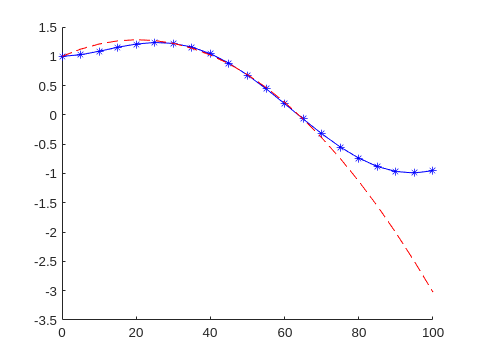

plot(x,polyval(flipud(c),x), 'r--') % flipud(c) want polyval wilt grootste coef eerst

2de graadsbenadering, nu arbitreire graad

clear all;
clf;
hold on

f = @(x) exp(-x/20) + sin(x/20)

f = function_handle with value:
    @(x)exp(-x/20)+sin(x/20)



graad = 4

graad = 4

x = linspace(0, 100, 21)

x =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


x_ = linspace(0, 100, graad+1)

x_ =      0    25    50    75   100


y = f(x_)

y =     1.0000    1.2355    0.6806   -0.5480   -0.9522



A = vander(x_)

A =            0           0           0           0           1
      390625       15625         625          25           1
     6250000      125000        2500          50           1
    31640625      421875        5625          75           1
   100000000     1000000       10000         100           1



c = A\y'

c =     0.0000
   -0.0000
    0.0003
    0.0130
    1.0000


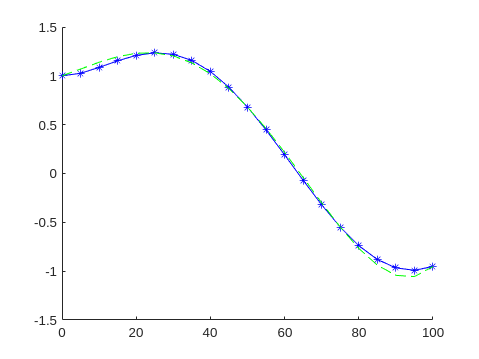

plot(x,f(x), 'b*-')
plot(x,polyval(c,x), 'g--')

Maximale graad is het aantal punten in de x_ linspace.

condA = cond(A)

condA = 1.0546e+08


epsilon = 1e-6 * randn(size(y))

epsilon = 1.0e-05 *

    0.1419    0.0292    0.0198    0.1588   -0.0804


ytilde = y .* (1 + epsilon)

ytilde =     1.0000    1.2355    0.6806   -0.5480   -0.9522



ctilde = A\y'

ctilde =     0.0000
   -0.0000
    0.0003
    0.0130
    1.0000


deltac = c - ctilde

deltac =      0
     0
     0
     0
     0


nu berekenen of de ongelijkheid geld: ∥c − ˜c∥ / ∥c∥ ≤ κ(A) ∥∆y∥ / ∥y∥ 

norm(deltac)/norm(ctilde)

ans = 0

condA*norm(epsilon)/norm(ytilde)

ans = 118.5884

Het is een lsecht idee om de graad hoog te kiezen omdat het conditiegetal van A dan enorm groot wordt wat leid tot een zeer slechte benadering.